# MSE491 Lab 1

% Group B2
% Jaehong Kim
% Tanya Nookut

## Time Specification

clear all
t = linspace(-1,1,10000);
freq_1 = 3; % Hz
signal_1 = sin(2*pi*freq_1*t);
freq_2 = 5; % Hz
signal_2 = sin(2*pi*freq_2*t);
% Sampling frequency (Fs) : 10000 Hertz 
% Sampling time (Ts) : 1/Fs seconds = 1e-4 sec

## Plot

plot(t,signal_1,'color','k','LineWidth',2)
grid on
grid minor
hold on
plot(t,signal_2,'--','color','m','LineWidth',2)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',12)
xlim([min(t) max(t)])
% Find largest signal
max_1 = max(signal_1);
max_2 = max(signal_2);
if max_1 > max_2
    max = max_1;
    min = min(signal_1);
else
    max = max_2;
    min = min(signal_2);
end
ylim([min-0.5 max+0.5])
xlabel('Time (s)','FontWeight','bold','FontSize',14)
ylabel('Amplitude (v)','FontWeight','bold','FontSize',14)
legend('\lambda_1','\Theta_1^2')
hold off
saveas(gcf,'fig_1','svg')
saveas(gcf,'fig_1','png')

## 3-D Circle

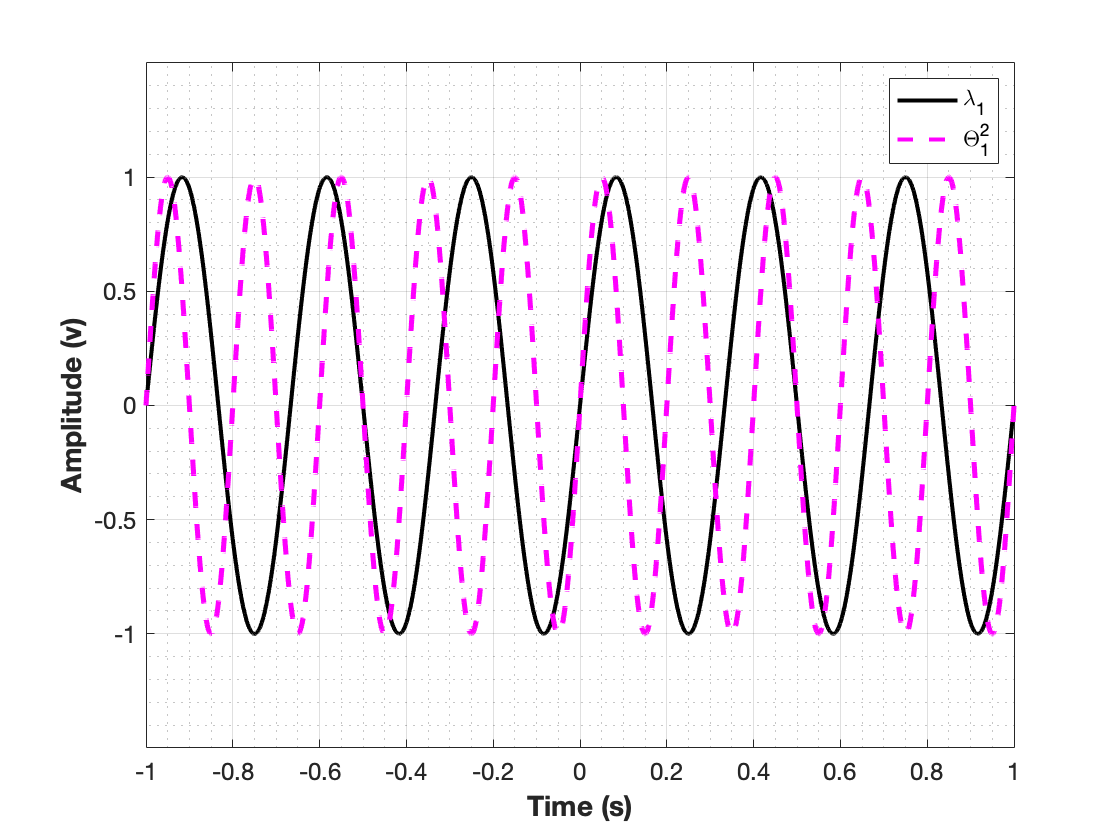

figure;
radii = 1:2:100;
z_amp = 0:length(radii)-1;
for i = 1:length(radii)

    theta = -pi:0.01:pi;
    x = radii(i)*cos(theta);
    y = radii(i)*sin(theta);
    z = zeros(1,numel(x)) + z_amp(i);
    plot3(x,y,z)
    hold on
end
hold off
saveas(gcf,'fig_2','svg')
saveas(gcf,'fig_2','png')

## Continuous and discrete signal generation

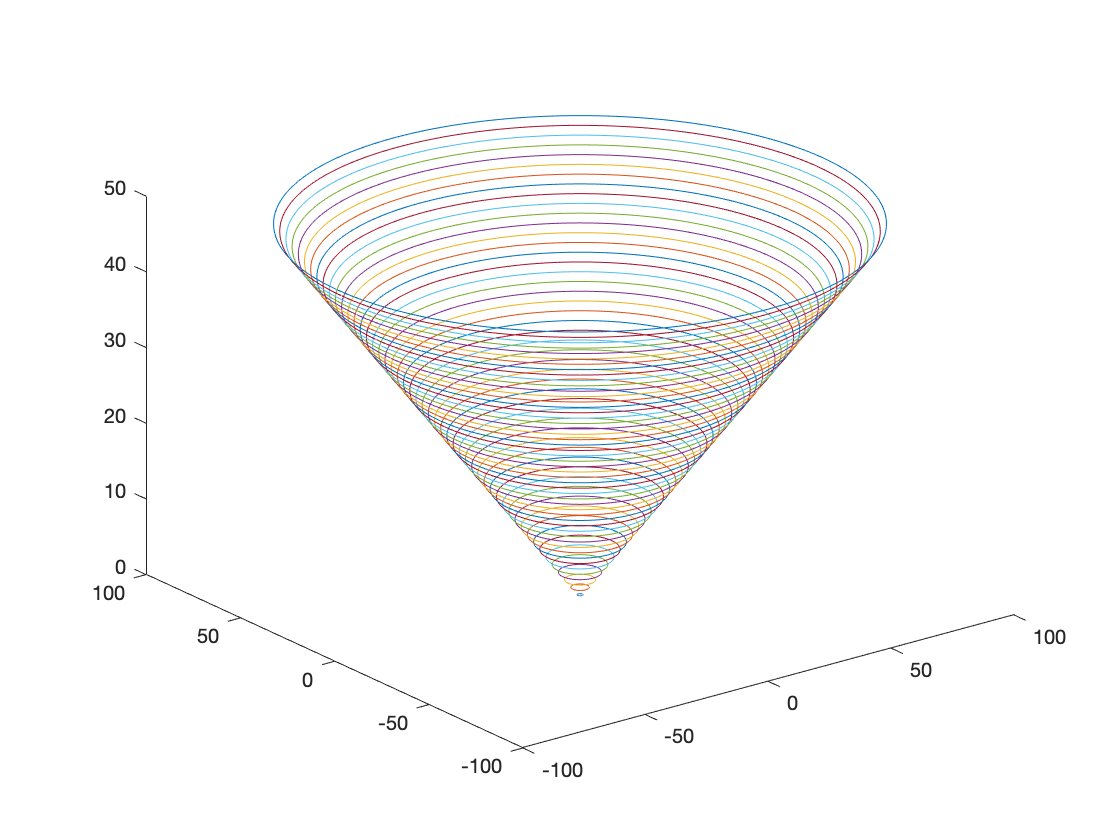

clc;
global time_domain


Fs = 1000; % samples/s
Ts = 1/Fs;

% Input interval
t1 = input('enter the starting time =    ');
t2 = input('enter the ending time =      ');
time_domain = input('enter the time domain =      ',"s"); % Continuous or discrete
figure;
t = t1:Ts:t2;
[m,n] = size(t); % size of the time varialbe 't'
r = zeros(m,n);
sqwave = square(4*pi*t); %period 0.5 and amplitude 1.

if strcmp(time_domain,'Continuous') == 1
    % Unit step function
    unitstep = t>=0;
    subplot(2,2,1)
    plot(t,unitstep)
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Step');
    
    % Unit impulse function
    impulse = t==0;
    subplot(2,2,2)
    plot(t,impulse)
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Impulse');
    
    % Unit ramp function
    ramp = t.*unitstep;
    subplot(2,2,3)
    plot(t,ramp)
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Ramp');
    
    % Square wave
    sqwave = square(4*pi*t); %period 0.5 and amplitude 1.
    subplot(2,2,4)
    plot(t,sqwave)
    xlabel('Time');
    ylabel('Amplitude');
    title('�Square wave');
    
elseif strcmp(time_domain,'Discrete') == 1
    
    % Unit step function
    subplot(2,2,1)
    for i = 1:n
        if t(i) >= 0 
            r(i) = 1;
        else
            r(i) = 0;
        end
    end
    stem(t,r);
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Step');
    
    % Unit impulse function
    subplot(2,2,2)
    for i = 1:n
        if t(i) ==0 
            r(i) = 1;
        else
            r(i) = 0;
        end
    end
    stem(t,r);
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Impulse');
    
    % Unit ramp function
    subplot(2,2,3)
    for i = 1:n
        if t(i) >= 0 
            r(i) = t(i);
        else
            r(i) = 0;
        end
    end
    stem(t,r);
    xlabel('Time');
    ylabel('Amplitude');
    title('Unit Ramp');
   
    % Square wave
    subplot(2,2,4)
    stem(t,sqwave)
end

## Amplitude Modulator

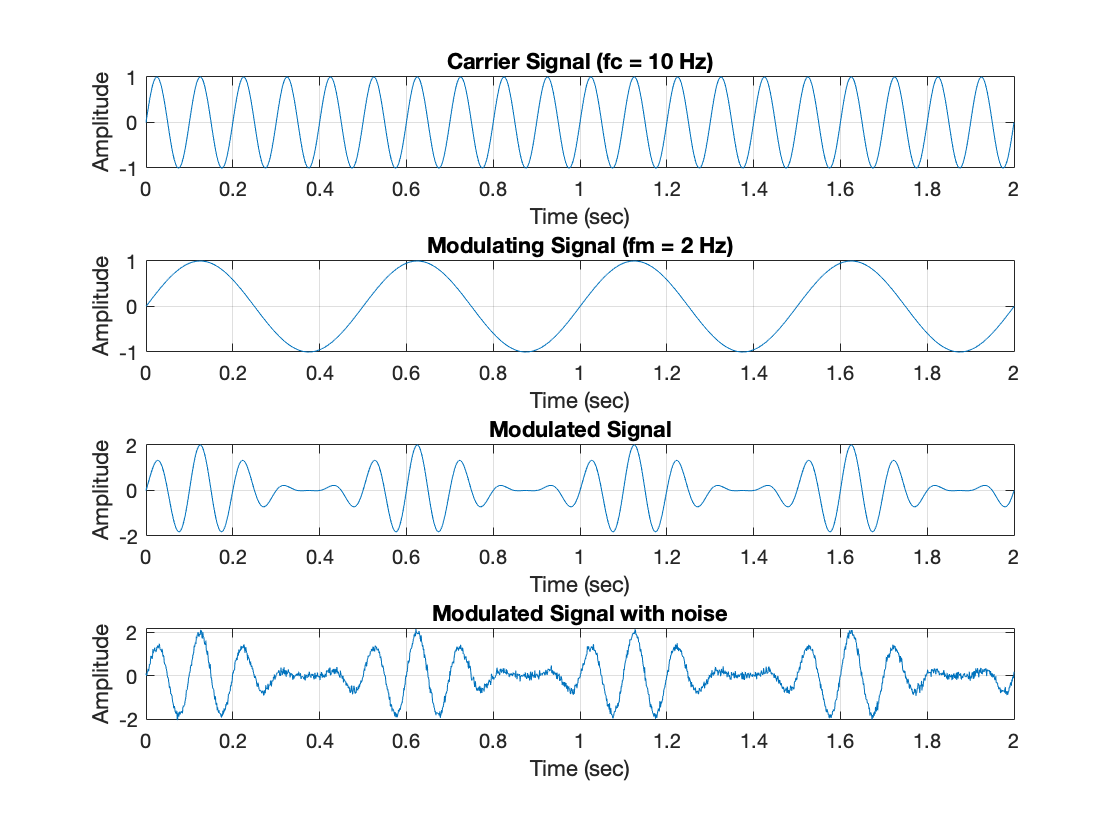

clc;
clear all;

m = 1; % Modulation sensitivity (m < 1 = undermodulation & m > 1 = overmodulation)

% Modulating signal generation 
Fs = 1000;                 % Number of samples
Am = 1;                    % Amplitude of modulating signal
fm = 2;                    % Frequency of modulating signal
Ts = 1/Fs;                 % Time period of modulating signal
t = 0:Ts:2;                % Total time for simulation
y_m = Am*sin(2*pi*fm*t);   % Eqation of modulating signal

% Carrier signal generation 
Ac = Am/m;                 % Amplitude of carrier signal [ where, modulation Index (m)=Am/Ac ]
fc = 10;                   % Frequency of carrier signal
Tc = 1/fc;                 % Time period of carrier signal
y_c= Ac*sin(2*pi*fc*t);    % Eqation of carrier signal

% Modulated signal
y = Ac*(1+m*sin(2*pi*fm*t)).*sin(2*pi*fc*t); % Equation of Amplitude

% Add noise to modulated signal
SNR = 20; % Signal to noise ratio (dB)
NoiseSignal = awgn(y, SNR);

% Plot
figure;

subplot(4,1,1); % Graphical representation of carrier signal
plot(t,y_c), grid on;
title('Carrier Signal (fc = 10 Hz)');
xlabel('Time (sec)');
ylabel('Amplitude');

subplot(4,1,2); % Graphical representation of modulating signal
plot(t,y_m), grid on;
title('Modulating Signal (fm = 2 Hz)');
xlabel('Time (sec)');
ylabel('Amplitude');

subplot(4,1,3); % Graphical representation of AM signal
plot(t,y), grid on;
title('Modulated Signal');
xlabel('Time (sec)');
ylabel('Amplitude');

subplot(4,1,4); % Graphical representation of AM signal with white Gaussian noise
plot(t,NoiseSignal), grid on;
title('Modulated Signal with noise');
xlabel('Time (sec)');
ylabel('Amplitude');

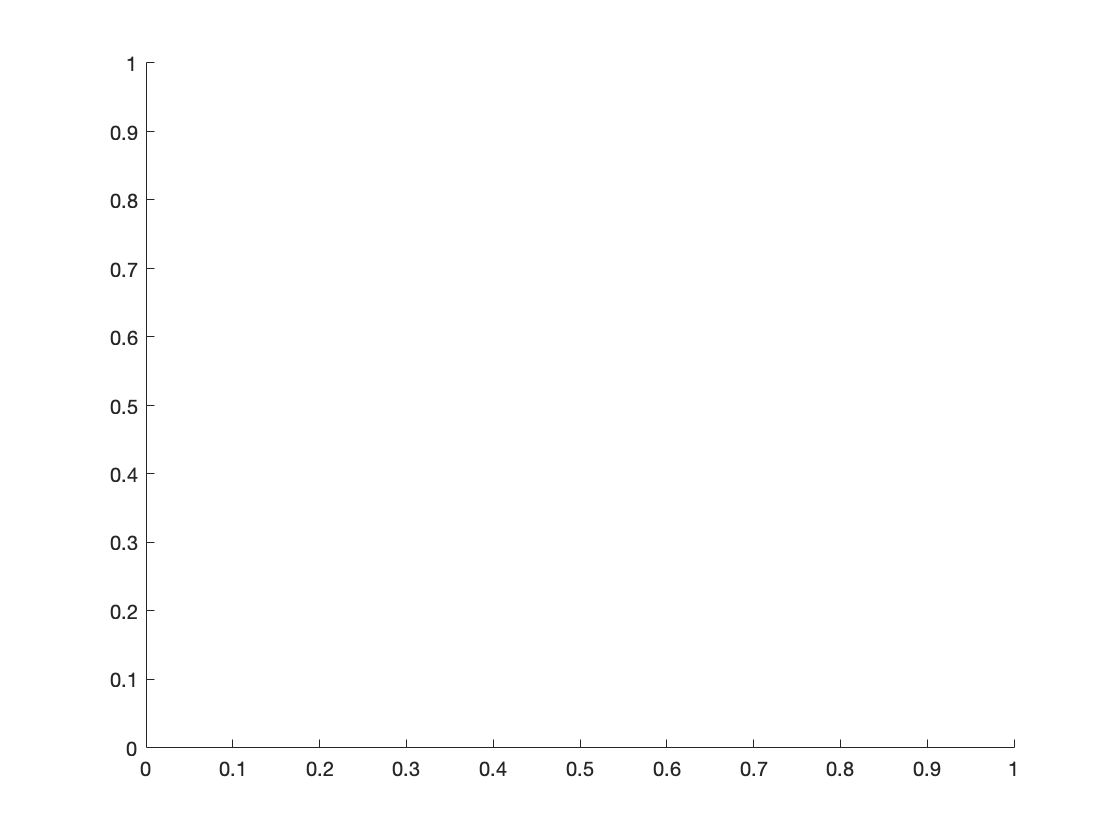


% Animation
figure;
axis tight
curve = animatedline;

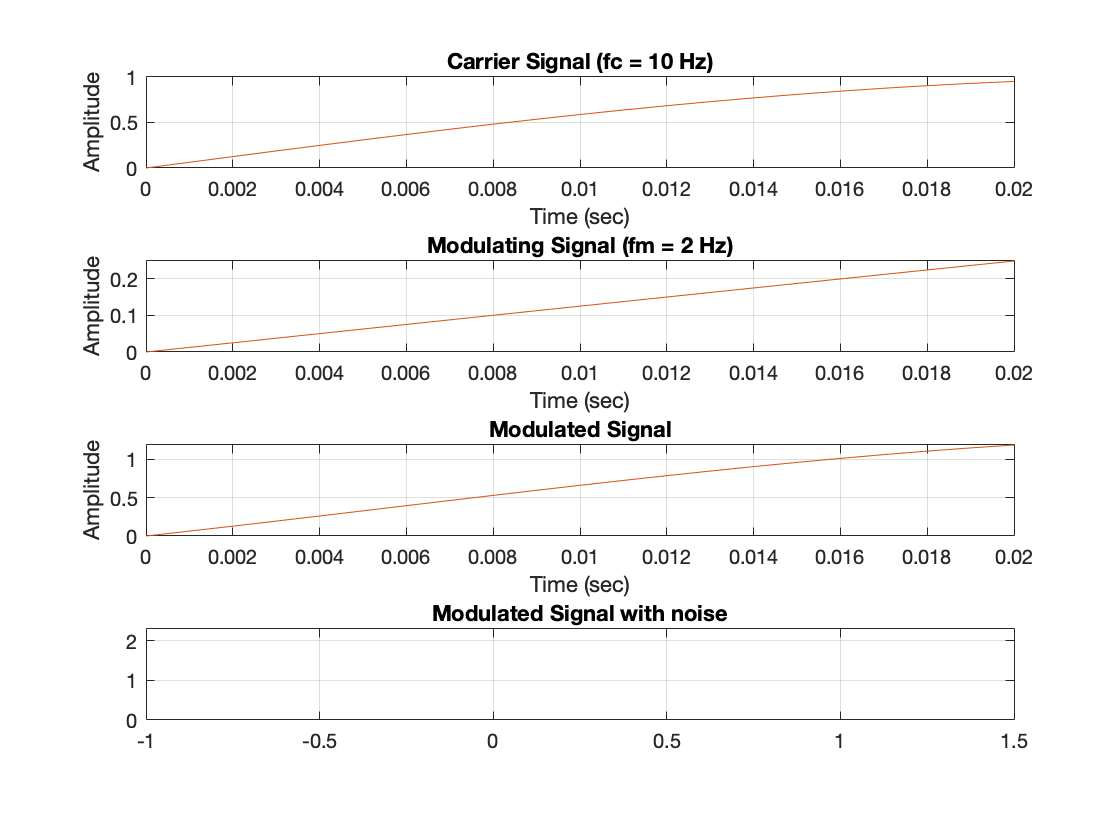

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.
Error in xlabel (line 65)
    h = get(ax,'XLabel');


for i = 1:length(t)
    subplot(4,1,1); 
    plot(t(i), y_c(i)), grid on
    hold on
    plot(t(1:i), y_c(1:i))
    title('Carrier Signal (fc = 10 Hz)');
    xlabel('Time (sec)');
    ylabel('Amplitude');
   
    subplot(4,1,2) 
    plot(t(i), y_m(i)), grid on
    hold on
    title('Modulating Signal (fm = 2 Hz)');
    xlabel('Time (sec)');
    ylabel('Amplitude');
    plot(t(1:i), y_m(1:i))
    
    subplot(4,1,3)
    plot(t(i), y(i)), grid on
    hold on
    title('Modulated Signal');
    xlabel('Time (sec)');
    ylabel('Amplitude');
    plot(t(1:i), y(1:i))
    
    subplot(4,1,4)
    plot(t(i), NoiseSignal(i)), grid on
    hold on
    title('Modulated Signal with noise');
    xlabel('Time (sec)');
    ylabel('Amplitude'); 
    plot(t(1:i), NoiseSignal(1:i))

    pause(0.1)
    
    if i ~= length(t)
        clf
    end
end